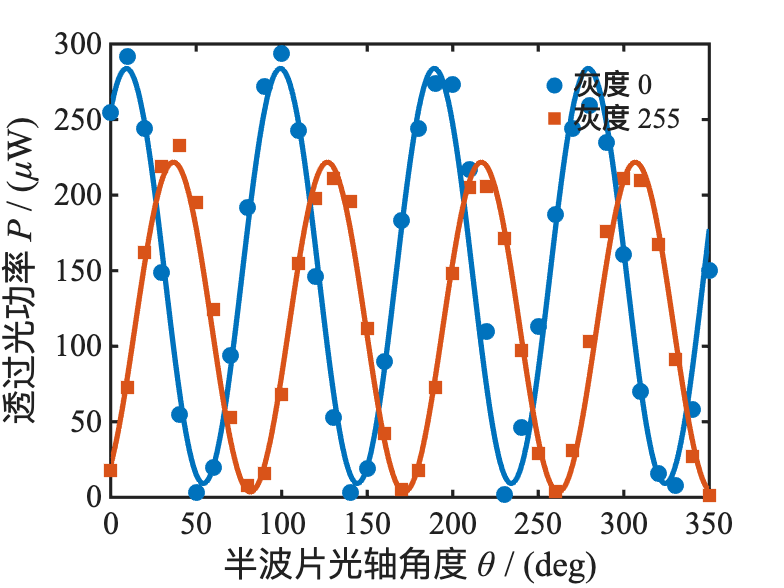

clear; clc; close all;

%% Global Publication Aesthetic Settings
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultLineLineWidth', 1.5);
set(groot, 'defaultAxesTickDir', 'in');
set(groot, 'defaultAxesBox', 'on');

figDir = fullfile("tex", "fig");
if ~exist(figDir, "dir")
    mkdir(figDir);
end

%% Data: Embedded directly from CSV files
angle = (0:10:350)';

p0 = [
    255; 292; 244; 149; 55; 3; 20; 94; 192; 272; 294; 243;
    146; 53; 3; 19; 90; 183; 244; 274; 273; 217; 110; 2;
    46; 113; 187; 244; 259; 235; 161; 70; 16; 8; 58; 150
];

p255 = [
    18; 73; 162; 219; 233; 195; 124; 53; 8; 16; 68; 155;
    198; 211; 196; 112; 42; 5; 18; 73; 148; 205; 206; 171;
    97; 29; 4; 31; 103; 176; 211; 210; 167; 91; 27; 1
];

contrast = p255 ./ p0;

gray = [0; 25; 50; 75; 100; 125; 150; 175; 200; 225; 250; 255];
power = [2; 6; 16; 38; 64; 87; 106; 124; 141; 157; 170; 173];

%% 计算最大对比度
[maxContrast, idx] = max(contrast);
bestAngle = angle(idx);

%% Figure 1: Power vs half-wave plate angle
X = [ones(size(angle)), cosd(4 * angle), sind(4 * angle)];
beta0 = X \ p0;
beta255 = X \ p255;

% 物理基线修正：抬升直流偏置以补偿暗背景
min_p0_fit = beta0(1) - sqrt(beta0(2)^2 + beta0(3)^2); 
if min_p0_fit < min(p0)
    beta0(1) = beta0(1) + (min(p0) - min_p0_fit);
end

xfit = linspace(0, 350, 600)';
Xfit = [ones(size(xfit)), cosd(4 * xfit), sind(4 * xfit)];

p0fit = Xfit * beta0;
p255fit = Xfit * beta255;

figure("Color", "w", "Position", [100, 100, 600, 450]);
scatter(angle, p0, 40, "o", "filled", "MarkerFaceColor", "#0072BD"); hold on;
scatter(angle, p255, 40, "s", "filled", "MarkerFaceColor", "#D95319");

plot(xfit, p0fit, "-", "LineWidth", 2, "Color", "#0072BD", "HandleVisibility", "off");
plot(xfit, p255fit, "-", "LineWidth", 2, "Color", "#D95319", "HandleVisibility", "off");

xlim([0 350]);
xlabel("半波片光轴角度 \theta / (deg)", "Interpreter", "tex");
ylabel("透过光功率 \itP\rm / (\muW)", "Interpreter", "tex");
% 图例恢复至内部默认位置，并保持无边框清爽样式
legend("灰度 0", "灰度 255", "Box", "off");

exportgraphics(gcf, fullfile(figDir, "power_angle.png"), "Resolution", 600);

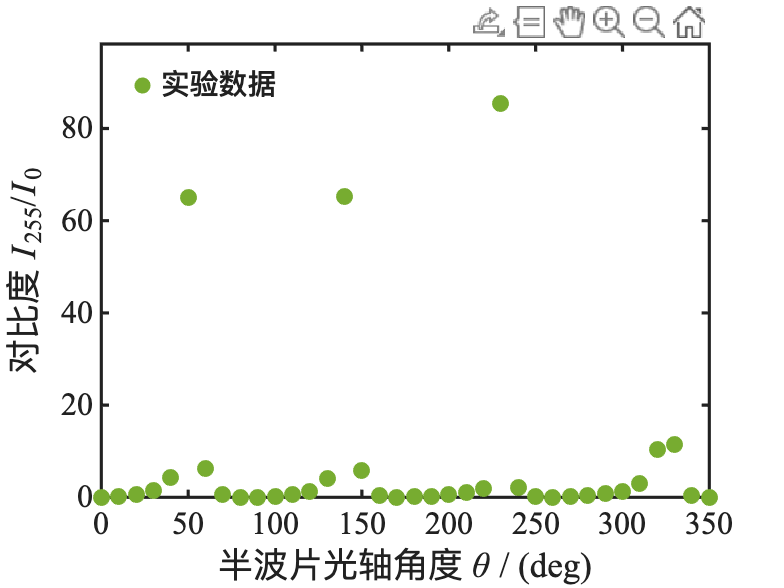


%% Figure 2: Contrast vs angle
figure("Color", "w", "Position", [150, 150, 600, 450]);
scatter(angle, contrast, 40, "filled", "MarkerFaceColor", "#77AC30");

xlim([0 350]);
ylim([0 maxContrast * 1.15]); 
xlabel("半波片光轴角度 \theta / (deg)", "Interpreter", "tex");
ylabel("对比度 \itI\rm_{255}/\itI\rm_0", "Interpreter", "tex");
legend("实验数据", "Location", "northwest", "Box", "off");

exportgraphics(gcf, fullfile(figDir, "contrast_angle.png"), "Resolution", 600);

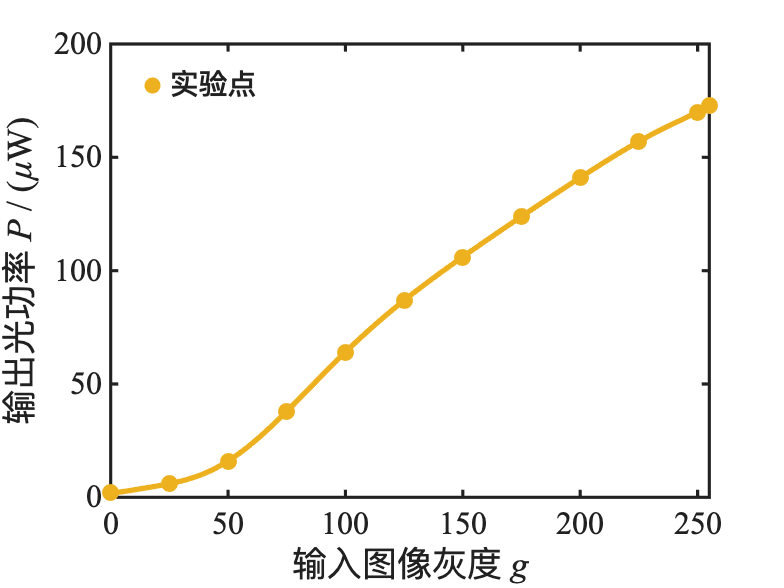


%% Figure 3: Gray response
polyDegree = 10; 
[coef, S, mu] = polyfit(gray, power, polyDegree);
grayFit = linspace(min(gray), max(gray), 300);
powerFit = polyval(coef, grayFit, S, mu);

residual = power - polyval(coef, gray, S, mu);
ssRes = sum(residual.^2);
ssTot = sum((power - mean(power)).^2);
R2 = 1 - ssRes / ssTot;

figure("Color", "w", "Position", [200, 200, 600, 450]);
scatter(gray, power, 40, "filled", "MarkerFaceColor", "#EDB120"); hold on;
plot(grayFit, powerFit, "-", "LineWidth", 2, "Color", "#EDB120", "HandleVisibility", "off");

xlim([0 255]);
xlabel("输入图像灰度 \itg\rm", "Interpreter", "tex");
ylabel("输出光功率 \itP\rm / (\muW)", "Interpreter", "tex");

legend(sprintf("实验点 "), ...
       "Location", "northwest", "Interpreter", "tex", "Box", "off");

exportgraphics(gcf, fullfile(figDir, "gray_response.png"), "Resolution", 600);


%% Print fitting results
fprintf("--------------------------------------------------\n");

--------------------------------------------------


fprintf("Best angle = %.0f deg\n", bestAngle);

Best angle = 230 deg


fprintf("Max contrast = %.2f\n", maxContrast);

Max contrast = 85.50


fprintf("Cubic fit successfully computed with centering and scaling.\n");

Cubic fit successfully computed with centering and scaling.


fprintf("R^2 = %.4f\n", R2);

R^2 = 1.0000


fprintf("--------------------------------------------------\n");

--------------------------------------------------
